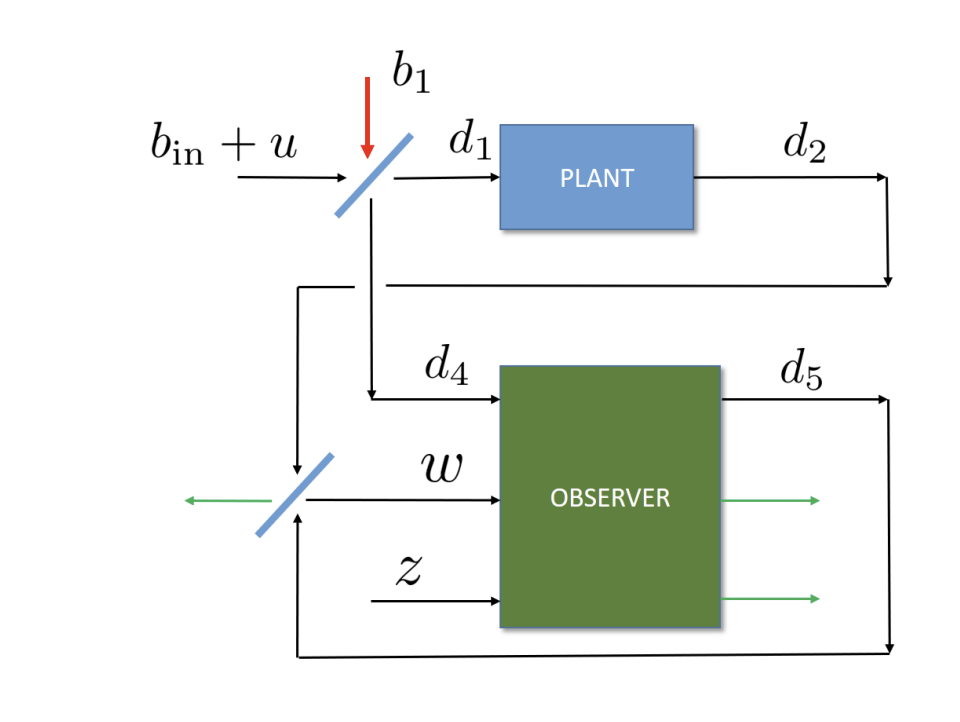

function quantum_luenberger_fig4_mean()
%===========================================================
% Coherent Quantum Luenberger Observer — Fig. 4 (MEAN dynamics)
% Robust MATLAB simulation based on Gough & Amini (2016).
%
% Key idea:
%   Simulate the mean (expectation) dynamics, where vacuum noises have zero mean.
%   Use the paper's error dynamics:
%       e_dot = (A - (1/sqrt(2)) L C) e
%   with plant:
%       a_dot = A a + B u(t)
%   and observer:
%       a_tilde = a - e
%
% Reference: Gough & Amini, arXiv:1609.06454, Fig.4 and Eq.(error drift). 
%===========================================================

clear; clc; close all;

%% ---- Parameters (edit) ----
gamma = 2.0;         % damping rate γ
omega = 8.0;         % cavity frequency ω
L     = 3.0;         % coherent Luenberger gain (scalar)
T     = 4.0;         % simulation horizon
dt    = 1e-3;        % time step

% Initial conditions
a0    = 1.0 + 0.0i;      % initial plant mode (mean)
at0   = -0.6 + 0.2i;     % initial observer mode (mean)

% Disturbance/drive u(t) injected as b_in -> b_in + u(t) (paper)
u_amp  = 0.0;        % set e.g. 1.0 to test disturbance
u_freq = 1.0;        % Hz

%% ---- Single-mode plant matrices (paper Eq. (8)) ----
A = -(gamma/2 + 1i*omega);
B = -sqrt(gamma);
C =  sqrt(gamma);

% Error drift from Fig.4 algebra in the paper:
Aeff = A - (1/sqrt(2))*L*C;

fprintf('A    = %.4f%+.4fi\n', real(A), imag(A));
fprintf('Aeff = %.4f%+.4fi\n', real(Aeff), imag(Aeff));
fprintf('Re(Aeff) = %.4f (must be < 0 for convergence)\n', real(Aeff));

%% ---- Time loop ----
N = floor(T/dt) + 1;
t = (0:N-1)*dt;

a  = zeros(1,N);
at = zeros(1,N);
e  = zeros(1,N);

a(1)  = a0;
at(1) = at0;
e(1)  = a(1) - at(1);

for k = 1:N-1
    u = u_amp * sin(2*pi*u_freq*t(k));

    % Plant mean dynamics: <a_dot> = A <a> + B u(t)
    a(k+1) = a(k) + dt*(A*a(k) + B*u);

    % Error mean dynamics: <e_dot> = (A - (1/sqrt2) L C) <e>
    e(k+1) = e(k) + dt*(Aeff*e(k));

    % Observer mean reconstruction
    at(k+1) = a(k+1) - e(k+1);
end

%% ---- Plots ----
figure; plot(t, real(a), t, real(at), 'LineWidth', 1.3);
grid on; xlabel('t'); ylabel('Real part');
legend('Plant: Re(a)','Observer: Re(\tilde a)','Location','best');
title('Fig.4 coherent observer (mean dynamics): real parts');

figure; plot(t, imag(a), t, imag(at), 'LineWidth', 1.3);
grid on; xlabel('t'); ylabel('Imag part');
legend('Plant: Im(a)','Observer: Im(\tilde a)','Location','best');
title('Fig.4 coherent observer (mean dynamics): imaginary parts');

figure; semilogy(t, abs(e).^2, 'LineWidth', 1.5);
grid on; xlabel('t'); ylabel('|e|^2 (log)');
title('Mean tracking error power: |a-\tilde a|^2');

end


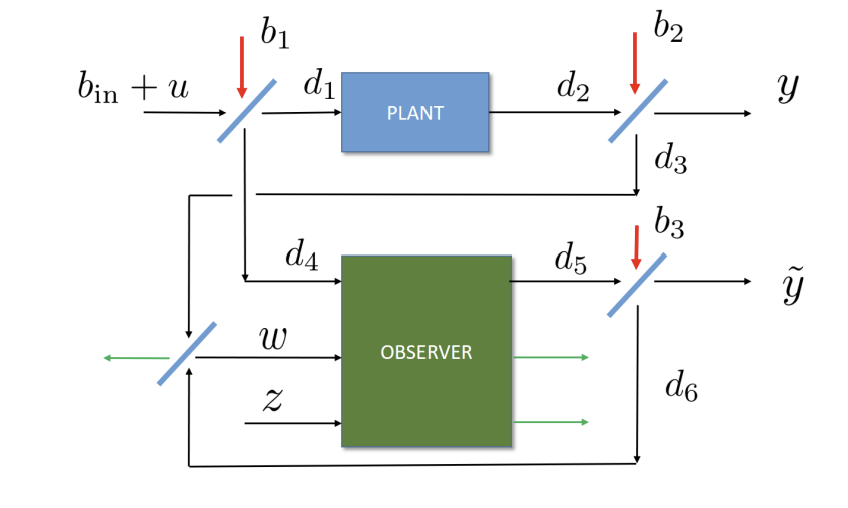

function quantum_luenberger_fig5_verifiable_demo()
% Verifiable coherent quantum Luenberger observer (Figure 5-like network)
% Based on Gough & Amini (2016) — "How To Build A Quantum Coherent Observer".
%
% Network implemented (matching your diagram):
%   BS1:  (b_in + u) mixed with vacuum b1 -> d1 (to plant), d4 (to observer)
%   Plant: da = A a dt + B d1 ; d2 = C a dt + d1
%   BS2:  d2 mixed with vacuum b2 -> y (measured), d3 (down-branch)
%   Observer: dã = A ã dt + B d4 - L dW - L dZ* ; d5 = C ã dt + d4
%   BS3:  d5 mixed with vacuum b3 -> ytilde, d6 (down-branch)
%   BS4:  d3 mixed with d6 -> w, z (to observer)
%   Verification output: v = (y - ytilde)/sqrt(2)  (eq. (10) structure)
%
% Notes:
% - This is a numerical stochastic simulation of a linear QSDE network.
% - Operator nature is not simulated explicitly; we simulate complex amplitudes
%   driven by complex Wiener increments representing vacuum inputs.
%

%% ---------------- Parameters ----------------
gamma = 2.0;        % damping rate γ
omega = 8.0;        % cavity frequency ω
Lgain = 3.0;        % coherent Luenberger gain L (scalar)
T     = 4.0;        % total time
dt    = 1e-3;       % step
M     = 400;        % Monte Carlo trajectories

% Optional classical drive/disturbance u(t) injected at input as b_in -> b_in + u(t)
u_amp  = 0.0;       % set >0 to test disturbance rejection
u_freq = 1.0;       % Hz

% Initial conditions
a0  = 1.0 + 0.0i;     % plant initial mode
at0 = -0.6 + 0.2i;    % observer initial mode

%% ---------------- Single-mode plant matrices ----------------
A = -(gamma/2 + 1i*omega);
B = -sqrt(gamma);
C =  sqrt(gamma);

N = floor(T/dt) + 1;
t = (0:N-1)*dt;

%% ---------------- Ensemble stats ----------------
Ea   = zeros(1,N);    % E[a]
Eat  = zeros(1,N);    % E[a_tilde]
Ee2  = zeros(1,N);    % E[|a-a_tilde|^2]
Ev2  = zeros(1,N);    % E[|v|^2]
EvI  = zeros(1,N);    % E[Re(v)] (homodyne-like quadrature with theta=0)

%% ---------------- Monte Carlo ----------------
for m = 1:M
    a  = a0;
    at = at0;

    % initialize delayed network signals
    d5_prev = 0;   % observer output increment at previous step (for forming d6 etc.)
    d2_prev = 0;

    for k = 1:N
        % record current error and verification stats
        e = a - at;
        Ea(k)  = Ea(k)  + a;
        Eat(k) = Eat(k) + at;
        Ee2(k) = Ee2(k) + abs(e)^2;

        if k == N
            break;
        end

        % classical drive
        u = u_amp * sin(2*pi*u_freq*t(k));

        % vacuum / input field increments (complex Wiener)
        dB_in = cwn(dt);
        dB1   = cwn(dt);
        dB2   = cwn(dt);
        dB3   = cwn(dt);

        % ---------------- BS1: split input to plant & observer (no cloning) ----------------
        dD1 = ((dB_in + u*dt) + dB1)/sqrt(2);   % to plant
        dD4 = ((dB_in + u*dt) - dB1)/sqrt(2);   % to observer

        % ---------------- Plant QSDE ----------------
        % da = A a dt + B d1
        a_next = a + A*a*dt + B*dD1;
        % d2 = C a dt + d1
        dD2 = C*a*dt + dD1;

        % ---------------- Observer output (needs current at) ----------------
        dD5 = C*at*dt + dD4;

        % ---------------- BS2: plant output splitter -> y and d3 ----------------
        % [y ; d3] = (1/sqrt2) [1  1; 1 -1] [d2; b2]
        dY  = (dD2 + dB2)/sqrt(2);   % measured plant-side output
        dD3 = (dD2 - dB2)/sqrt(2);   % down-branch

        % ---------------- BS3: observer output splitter -> ytilde and d6 ----------------
        dYt = (dD5 + dB3)/sqrt(2);   % measured observer-side output
        dD6 = (dD5 - dB3)/sqrt(2);   % down-branch

        % ---------------- BS4: combine d3 and d6 -> innovation w and auxiliary z ----------------
        % Choose a consistent 50/50 mixing that produces two orthogonal combinations.
        % Here:
        %   w = (d3 - d6)/sqrt2     (difference channel ~ output mismatch)
        %   z = (d3 + d6)/sqrt2     (sum channel, used as an "active" port via z*)
        dW = (dD3 - dD6)/sqrt(2);
        dZ = (dD3 + dD6)/sqrt(2);

        % ---------------- Observer QSDE with verifiable extension ----------------
        % Core Luenberger injection: -L w
        % Active/creation-type port: -L z*   (matches the paper's " - L z^*(t) " structure)
        at_next = at + A*at*dt + B*dD4 - Lgain*dW - Lgain*conj(dZ);

        % ---------------- Verification signal (like Eq. (10)) ----------------
        % v = (y - ytilde)/sqrt2  (field increment)
        dV = (dY - dYt)/sqrt(2);

        Ev2(k+1) = Ev2(k+1) + abs(dV)^2 / dt;   % normalize to "power" per unit time
        EvI(k+1) = EvI(k+1) + real(dV)/dt;      % crude homodyne-like current (theta=0)

        % advance
        a  = a_next;
        at = at_next;

        d2_prev = dD2; %#ok<NASGU>
        d5_prev = dD5; %#ok<NASGU>
    end
end

% averages
Ea  = Ea / M;
Eat = Eat / M;
Ee2 = Ee2 / M;
Ev2 = Ev2 / M;
EvI = EvI / M;

%% ---------------- Plots ----------------
figure; plot(t, real(Ea), t, real(Eat), 'LineWidth', 1.3);
grid on; xlabel('t'); ylabel('Re\{E[a]\}, Re\{E[\tilde a]\}');
legend('Plant','Observer','Location','best');
title('Verifiable coherent observer: mean real parts');

figure; plot(t, imag(Ea), t, imag(Eat), 'LineWidth', 1.3);
grid on; xlabel('t'); ylabel('Im\{E[a]\}, Im\{E[\tilde a]\}');
legend('Plant','Observer','Location','best');
title('Verifiable coherent observer: mean imaginary parts');

figure; semilogy(t, Ee2, 'LineWidth', 1.5);
grid on; xlabel('t'); ylabel('E[|a-\tilde a|^2] (log)');
title('Tracking error power');

figure; plot(t, Ev2, 'LineWidth', 1.5);
grid on; xlabel('t'); ylabel('E[|v|^2] (arb. units)');
title('Verification port power (v = (y-\tilde y)/\surd2)');

figure; plot(t, EvI, 'LineWidth', 1.2);
grid on; xlabel('t'); ylabel('E[Re(v)]/dt (arb. units)');
title('Homodyne-like quadrature (theta=0) of verification port');

%% ---------------- Sanity check: deterministic error drift ----------------
Aeff = A - (1/sqrt(2))*Lgain*C;
fprintf('A = %.4f%+.4fi\n', real(A), imag(A));
fprintf('Aeff = A - (1/sqrt(2)) L C = %.4f%+.4fi\n', real(Aeff), imag(Aeff));
fprintf('Re(Aeff) = %.4f (should be < 0 for mean convergence)\n', real(Aeff));

end

%% ---------- helper: complex white-noise increment (vacuum) ----------
function dB = cwn(dt)
% complex Wiener increment with E[|dB|^2] = dt
dB = (randn() + 1i*randn())/sqrt(2) * sqrt(dt);
end
